# **Flux Variability analysis (FVA)**

Flux variability analysis (FVA) is a widely used computational tool for evaluating the minimum and maximum range of each reaction flux that can still satisfy the constraints using two optimisation problems for each reaction of interest $$^1$. 


$$\begin{array}{lll}
\max\limits _{v}/\min\limits _{v} & v_{j} \\
\text{s.t.} & Sv=0,\\
 & l\leq v\leq u,\\
& c_{T}v = c_{T}v*
\end{array}$$


where $v \in R^{n}$ represents the rate of each biochemical reaction, but typically an infinite set of steady state flux vectors exist can satisfy the same requirement for an optimal objective $$ c_{T}v* = c_{T}v$. As well as for the flux balance analysis (FBA), there are also many possible variations on flux variability analysis (FVA) $$^2$.

Depending on the size of the model you are using for the analysis, use:

- `fluxVariability()` function - for the low dimensional FVA;

- `fastFVA()` function - for the models with more than 1,000 reactions;

- [distributedFBA.jl](https://github.com/opencobra/COBRA.jl) - for high dimensional FVA, models larger than 10,000 reactions $$^2$;

## EQUIPMENT SETUP

If necessary, initialize the cobra toolbox:

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in FBA and FVA analysis, certain solvers are required:

% solverOK = changeCobraSolver(solverName, solverType, printLevel, unchecked)

The present tutorial can run with [glpk package](https://opencobra.github.io/cobratoolbox/deprecated/docs/cobra/solvers/changeCobraSolver.html), which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the [GUROBI](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md) package.

changeCobraSolver ('gurobi', 'all', 1);


 > Gurobi interface added to MATLAB path.
 > Solver for LPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQPproblems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


## PROCEDURE

In this tutorial, the provided model is a generic model of the human cellular metabolism, Recon 3D $$^3$. Therefore, we assume, that the cellular objectives include energy production or optimisation of uptake rates and by-product secretion for various physiological functions of the human body.

Before proceeding with the simulations, the path for the model needs to be set up:

% check if Recon3 exists:
% pathModel = '~/work/sbgCloud/data/models/unpublished/Recon3D_models/';
% filename = '2017_04_28_Recon3d.mat';
% load([pathModel, filename])
% model = modelRecon3model;
% clear modelRecon3model
% and if not
% select your own model, or use Recon2.0model instead filename='Recon3.0model';
global CBTDIR
load([CBTDIR filesep 'test' filesep 'models' filesep 'Recon2.0model.mat']);
model = Recon2model;
model.rxns = strrep(model.rxns, '(', '[');
model.rxns = strrep(model.rxns, ')', ']');
clear Recon2model

The metabolites structures and reactions are from the Virtual Metabolic Human database (VMH, [http://vmh.life](http://vmh.life)).

## TROUBLESHOOTING

If there are multiple energy sources available in the model, specify more constraints.

If we do not do that, we will have additional carbon and oxygen energy sources available in the cell and the maximal ATP production. 

To avoid this issue, all external carbon sources need to be closed.

%Closing the uptake of all energy and oxygen sources
idx=strmatch('Exchange/demand reaction',model.subSystems);
c=0;
for i=1:length(idx)
    if model.lb(idx(i))~=0
        c=c+1;
        uptakes{c}=model.rxns{idx(i)};
    end
end
% If you use Recon3.0 model, than:
% modelalter = model;
% modelalter = changeRxnBounds(modelalter, uptakes, 0, 'b');
% modelalter = changeRxnBounds(modelalter, 'EX_HC00250[e]', -1000, 'l');

% The alternative way to do that, in case you were using another large model, 
% that does not contain defined Subsystem is
% to find uptake exchange reactions with following codes:
% [selExc, selUpt] = findExcRxns(model);
% uptakes = model.rxns(selUpt);

% Selecting from the exchange uptake reactions those 
% which contain at least 1 carbon in the metabolites included in the reaction:
 subuptakeModel = extractSubNetwork(model, uptakes);
 hiCarbonRxns = findCarbonRxns(subuptakeModel,1);
% Closing the uptake of all the carbon sources
 modelalter = model;
 modelalter = changeRxnBounds(modelalter, hiCarbonRxns, 0, 'b');
% Closing other oxygen and energy sources
 exoxygen = {'EX_adp'
    'EX_amp[e]'
    'EX_atp[e]'
    'EX_co2[e]'
    'EX_coa[e]'
    'EX_fad[e]'
    'EX_fe2[e]'
    'EX_fe3[e]'
    'EX_gdp[e]'
    'EX_gmp[e]'
    'EX_gtp[e]'
    'EX_h[e]'
    'EX_h2o[e]'
    'EX_h2o2[e]'
    'EX_nad[e]'
    'EX_nadp[e]'
    'EX_no[e]'
    'EX_no2[e]'
    'EX_o2s[e]'};
for i = 1:length (exoxygen)
    modelalter = changeRxnBounds (modelalter, exoxygen{i}, 0, 'l');
end

In this example, we are analysing the variability of several reactions from the human cellular metabolism in the aerobic and anaerobic state. 

For each simulation, the original model will be copied to a new variable. This preserves the constraints of the original model and allows to perform simulations with new constraints. Additionally, this method of renaming the model avoids confusion while performing multiple simulations at the same time.

% modelfva1 represents aerobic condition
modelfva1 = modelalter;
% For Recon3.0 model
% modelfva1 = changeRxnBounds (modelfva1, 'EX_glc_D[e]', -20, 'l');
modelfva1 = changeRxnBounds (modelfva1, 'EX_glc[e]', -20, 'l');
modelfva1 = changeRxnBounds (modelfva1, 'EX_o2[e]', -1000, 'l');
% modelfva2 represents anaerobic condition
modelfva2 = modelfva1;
modelfva2 = changeRxnBounds (modelfva2, 'EX_o2[e]', 0, 'l');

## Standard FVA

The full spectrum of flux variability analysis options can be accessed using the command:

% [minFlux, maxFlux, Vmin, Vmax] = fluxVariability(model, optPercentage,...
%     osenseStr, rxnNameList, verbFlag, allowLoops, method);

The `optPercentage` parameter allows one to choose whether to consider solutions that give at least a certain percentage of the optimal solution. 

Setting the parameters  `osenseStr = 'min'` or `osenseStr = 'max'` determines whether the flux balance analysis problem is first solved with minimization or maximisation. 

The `rxnNameList` accepts a cell array list of reactions to selectively perform flux variability upon. This is useful for high-dimensional models where computation of a flux variability for all reactions is more time consuming:

% Selecting several reactions from the model that we want to analyse with FVA
rxnsList = {'DM_atp_c_'
    'ACOAHi'
    'ALCD21_D'
    'LALDO'
    'ME2m'
    'AKGDm'
    'PGI'
    'PGM'
    'r0062'};

The `verbFlag` input determines how much output to print. 

`allowLoops==0` invokes a mixed integer linear programming implementation of thermodynamically constrained flux variability analysis for each minimization or maximisation of a reaction rate. 

The `method` parameter input determines whether are the output flux vectors also minimise the `0-norm`, `1-norm` or `2-norm` whilst maximising or minimising the flux through one reaction. 

Running `fluxVariability()` on both models (`modelfva1`, `modelfva2`) will generate the minimum and maximum flux ranges of selected reactions, from rxnsList, in the network.

Run FVA analysis for the model with the constraints that simulates aerobic conditions:

[minFlux1, maxFlux1, Vmin1, Vmax1] = fluxVariability(modelfva1);

minFlux1 =    1.0e+03 *

         0
         0
         0
   -1.0000
         0
         0
   -1.0000
   -0.0682
         0


maxFlux1 =    1.0e+03 *

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6571
    0.0200
    1.0000
    1.0000


Vmin1 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
   -9.0328         0   -0.3575   -1.8017   -9.2028    0.0000   -0.1666  -20.2576    0.0000
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


Vmax1 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
   -9.0328         0   -0.3575   -1.8017   -9.2028    0.0000   -0.1666  -20.2576    0.0000
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


[minFlux1, maxFlux1, Vmin1, Vmax1] = fluxVariability(modelfva2);

[minFlux1, maxFlux1, Vmin1, Vmax1] = fluxVariability(modelfva1, [], [], rxnsList)

minFlux2 =    1.0e+03 *

         0
         0
         0
   -1.0000
         0
         0
   -0.2644
   -0.0402
         0


maxFlux2 =    1.0e+03 *

    0.0826
    0.1652
    1.0000
    1.0000
    1.0000
    0.0280
    0.0200
    0.0542
    0.1652


Vmin2 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
  -19.3226  -26.1787   -1.7640  -13.9937  -11.0973   -2.5152   -2.4127  -19.5854  -32.9262
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


Vmax2 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
  -19.3226  -26.1787   -1.7640  -13.9937  -11.0973   -2.5152   -2.4127  -19.5854  -32.9262
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


Run FVA analysis for the model with the constraints that simulates anaerobic conditions:

[minFlux2, maxFlux2, Vmin2, Vmax2] = fluxVariability(modelfva2, [], [], rxnsList) 

The additional `n × k` output matrices `Vmin` and `Vmax` return the flux vector for each of the `k ≤ n` fluxes selected for flux variability.

Further, plot and compare the FVA results from the both models:

ymax1 = maxFlux1;
ymin1 = minFlux1;
ymax2 = maxFlux2;
ymin2 = minFlux2;


maxf =     ymax1     ymax2 
    ______    ______

      1000    82.618
      1000    165.24
      1000      1000
      1000      1000
      1000      1000
    657.07        28
        20        20
      1000    54.206
      1000    165.24


maxf =table(ymax1, ymax2)

minf =      ymin1      ymin2 
    _______    _______

          0          0
          0          0
          0          0
      -1000      -1000
          0          0
          0          0
      -1000    -264.38
    -68.167     -40.21
          0          0


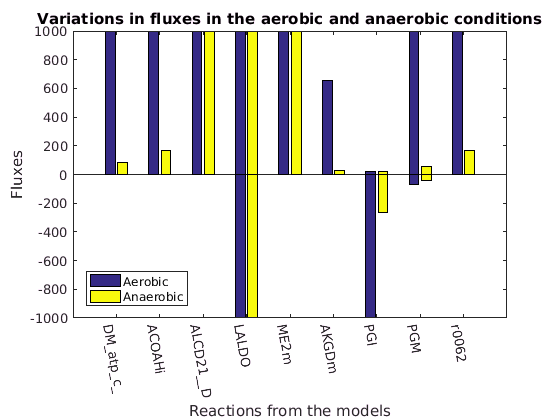

minf =table(ymin1, ymin2)
maxfxs = table2cell(maxf);
minfxs = table2cell(minf);

figure
plot1 = bar(cell2mat(maxfxs(1:end,:)));
hold on
plot2 = bar(cell2mat(minfxs(1:end,:)));

xticklabels({'DM_atp_c_', 'ACOAHi', 'ALCD21__D', 'LALDO',...
    'ME2m', 'AKGDm', 'PGI', 'PGM', 'r0062'})
set(gca, 'XTickLabelRotation',-80);
yticks([-1000 -800 -600 -400 -200 0 200 400 600 800 1000])
xlabel('Reactions from the models')
ylabel('Fluxes')
legend({'Aerobic', 'Anaerobic'}, 'Location', 'southwest')

title('Variations in fluxes in the aerobic and anaerobic conditions')

## Fast FVA

The code is as follows-

% [minFlux, maxFlux, optsol, ret, fbasol, fvamin, fvamax, statussolmin,...
% statussolmax] = fastFVA(model, optPercentage, objective, solverName,...
% rxnsList, matrixAS, cpxControl, strategy, rxnsOptMode)

The `fastFVA()` function returns vectors for the initial FBA in `fbasol` together with matrices `fvamin` and `fvamax` containing the flux values for each individual min/max problem.

## TROUBLESHOOTING

Note that for large models the memory requirements may become prohibitive.

The `fastFVA()` function only supports the [CPLX](https://opencobra.github.io/cobratoolbox/docs/solvers.html ) solver. For detail information, refer to the solver [installation guide](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md).

changeCobraSolver ('ibm_cplex', 'all', 1);


 > IBM ILOG CPLEX interface added to MATLAB path.
 > Solver for LP problems has been set to ibm_cplex.

 > IBM ILOG CPLEX interface added to MATLAB path.
 > Solver for MILP problems has been set to ibm_cplex.

 > IBM ILOG CPLEX interface added to MATLAB path.
 > Solver for QP problems has been set to ibm_cplex.
 > Solver ibm_cplex not supported for problems of type MIQP. Currently used: gurobi 
 > Solver ibm_cplex not supported for problems of type NLP. No solver set for this problemtype 


Run fast FVA analysis for the whole model with the constraints that simulates aerobic conditions:

[minFluxF1, maxFluxF1, optsol, ret, fbasol, fvamin,fvamax,...
    statussolmin, statussolmax] = fastFVA(modelfva1);

 > The CPLEX version has been determined as 1271.
 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 1, output 9.
 >> Size of stoichiometric matrix: (5063,7440)
 >> All reactions are solved (7440 reactions - 100%).
 >> 0 reactions out of 7440 are minimized (0.00%).
 >> 0 reactions out of 7440 are maximized (0.00%).
 >> 7440 reactions out of 7440 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 3 / 4 (LoopID = 4) <> [5581, 7440] / [5063, 7440].
 >> The number of reactions retrieved is 1860
 >> Log files will be stored at /home/vanja/fork-cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Wed Jul 12 15:55:04 2017
 >> #Task.ID = 3; logfile: cplexint_logfile_3.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you exp

Run fast FVA analysis for the whole model with the constraints that simulates anaerobic conditions:

[minFluxF2, maxFluxF2, optsol2, ret2, fbasol2, fvamin2, fvamax2,...
    statussolmin2, statussolmax2] = fastFVA(modelfva2);

 > The CPLEX version has been determined as 1271.
 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 1, output 9.
 >> Size of stoichiometric matrix: (5063,7440)
 >> All reactions are solved (7440 reactions - 100%).
 >> 0 reactions out of 7440 are minimized (0.00%).
 >> 0 reactions out of 7440 are maximized (0.00%).
 >> 7440 reactions out of 7440 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 3 / 4 (LoopID = 4) <> [5581, 7440] / [5063, 7440].
 >> The number of reactions retrieved is 1860
 >> Log files will be stored at /home/vanja/fork-cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Wed Jul 12 16:10:27 2017
 >> #Task.ID = 3; logfile: cplexint_logfile_3.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you exp

Plotting the results of the fast FVA and comparing them between the aerobic and anaerobic models:

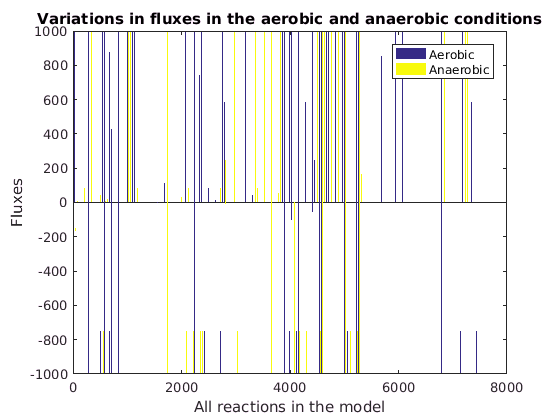

ymaxf1 = maxFluxF1;
yminf1 = minFluxF1;
ymaxf2 = maxFluxF2;
yminf2 = minFluxF2;

maxf =table(ymaxf1,ymaxf2);
minf =table(yminf1,yminf2);

maxf = table2cell(maxf);
minf = table2cell(minf);

figure
plot3 = bar(cell2mat(maxf(1:end,:)));
hold on
plot4 = bar(cell2mat(minf(1:end,:)));

xticks([0 2000 4000 6000 8000 10600])
yticks([-1000 -800 -600 -400 -200 0 200 400 600 800 1000])
xlabel('All reactions in the model')
ylabel('Fluxes')
legend({'Aerobic', 'Anaerobic'})
title('Variations in fluxes in the aerobic and anaerobic conditions')

## REFERENCES 

[1] Gudmundsson, S., Thiele, I. Computationally efficient flux variability analysis. *BMC Bioinformatics. *11, 489 (2010).

[2] Heirendt, L., Thiele, I., Fleming, R.M. DistributedFBA.jl: high-level, high-performance flux balance analysis in Julia. *Bioinformatics.* 33 (9), 1421-1423 (2017).

[3] Thiele, I., Price, N.D., Vo, T.D., Palsson B. Ø. Candidate Metabolic Network States in Human Mitochondria. Impact of diabetes, ischemia and diet. *J Bio Chem. *280 (12), 11683–11695 (2005).